# Machine Learning: Programming Exercise 1

## Linear Regression

In this exercise, you will implement linear regression and get to see it work on data.

### Files needed for this exercise

- `ex1.mlx` - MATLAB Live Script that steps you through the exercise

- ex1data1.txt - Dataset for linear regression with one variable

- ex1data2.txt - Dataset for linear regression with multiple variables

- `submit.m` - Submission script that sends your solutions to our servers

- *`warmUpExercise.m` - Simple example function in MATLAB

- *`plotData.m` - Function to display the dataset

- *`computeCost.m` - Function to compute the cost of linear regression

- *`gradientDescent.m` - Function to run gradient descent

- **`computeCostMulti.m` - Cost function for multiple variables

- **`gradientDescentMulti.m` - Gradient descent for multiple variables

- **`featureNormalize.m `- Function to normalize features

- **`normalEqn.m` - Function to compute the normal equations

****indicates files you will need to complete***

*****indicates optional exercises***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex1' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README.mlx` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README.mlx` and have checked for an existing solution before seeking help on the discussion forums.

## 1. A simple MATLAB function

The first part of this script gives you practice with MATLAB syntax and the homework submission process. In the file `warmUpExercise.m`, you will find the outline of a MATLAB function. Modify it to return a 5 x 5 identity matrix by filling in the following code:

When you are finished, save `warmUpExercise.m`, then run the code contained in this section to call `warmUpExercise().` 

**5x5 Identity Matrix:**

warmUpExercise()

You should see output similar to the following:

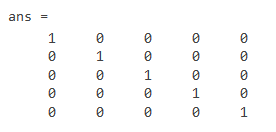

You can toggle between right-hand-side output and in-line output for printing results and displaying figures inside a Live Script by selecting the appropriate box in the upper right of the Live Editor window. 

### 1.1 Submitting Solutions

After completing a part of the exercise, you can submit your solutions for that section by running the section of code below, which calls the `submit.m` script. Your score for each section will then be displayed as output. **Enter your login and your unique submission token *****inside the command window***** when prompted. For future submissions of this exercise, you will only be asked to confirm your credentials.** Your submission token for each exercise is found in the corresponding homework assignment course page. New tokens can be generated if you are experiencing issues with your current token. You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter your login and token when prompted.*

## 2. Linear regression with one variable

In this part of this exercise, you will implement linear regression with one variable to predict profits for a food truck. Suppose you are the CEO of a restaurant franchise and are considering different cities for opening a new outlet. The chain already has trucks in various cities and you have data for profits and populations from the cities. You would like to use this data to help you select which city to expand to next.

The file `ex1data1.txt` contains the dataset for our linear regression problem. The first column is the population of a city and the second column is the profit of a food truck in that city. A negative value for profit indicates a loss. This script has already been set up to load this data for you.

### 2.1 Plotting the data

Before starting on any task, it is often useful to understand the data by visualizing it. For this dataset, you can use a scatter plot to visualize the data, since it has only two properties to plot (profit and population). Many other problems that you will encounter in real life are multi-dimensional and can't be plotted on a 2-d plot.

Run the code below to load the dataset from the data file into the variables X and y:

data = load('ex1data1.txt'); % read comma separated data
X = data(:, 1); y = data(:, 2);

Your job is to complete `plotData.m` to draw the plot; modify the file and fill in the following code:

Once you are finished, save `plotData.m,` and execute the code in this section which will call `plotData`. 

plotData(X,y)

The resulting plot should appear as in Figure 1 below:

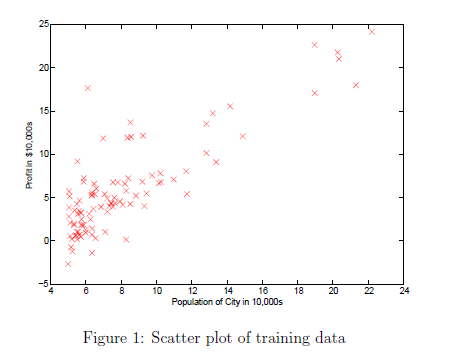

To learn more about the `plot` command, you can run the command `help plot` at the command prompt, type `plot()` inside the MATLAB Live Editor and click on the "(?)" tooltip, or you can search the [MATLAB documentation](https://www.mathworks.com/help/matlab/) for "plot". Note that to change the markers to red x's in the plot, we used the option: **'**`rx'` together with the `plot` command, i.e., 

### 2.2 Gradient Descent

In this section, you will fit the linear regression parameters to our dataset using gradient descent.

#### 2.2.1 Update Equations

The objective of linear regression is to minimize the cost function


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \;$$


where the hypothesis $h_{\theta}(x)$ is given by the linear model


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


Recall that the parameters of your model are the $\theta$ values. These are the values you will adjust to minimize cost $J(\theta)$. One way to do this is to use the batch gradient descent algorithm. In batch gradient descent, each iteration performs the update


$$\theta_j :=\theta_j -\alpha \frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\;\;\;\;\;\left(\textrm{simultaneously}\;\textrm{update}\;\theta_{j\;} \;\textrm{for}\;\textrm{all}\;j\right)$$


With each step of gradient descent, your parameters $j$ come closer to the optimal values that will achieve the lowest cost $J(\theta)$.

**Implementation Note:** We store each example as a row in the the `X` matrix in MATLAB. To take into account the intercept term ($\theta_0$), we add an additional first column to `X` and set it to all ones. This allows us to treat $\theta_0$ as simply another 'feature'.

#### 2.2.2 Implementation

In this script, we have already set up the data for linear regression. In the following lines, we add another dimension to our data to accommodate the $\theta_0$ intercept term. Run the code below to initialize the parameters to 0 and the learning rate `alpha` to 0.01. 

m = length(X); % number of training examples
X = [ones(m,1),data(:,1)]; % Add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters
iterations = 1500;
alpha = 0.01;

#### 2.2.3 Computing the cost $\mathit{\mathbf{J}}\left(\theta \right)$

As you perform gradient descent to minimize the cost function $J\left(\theta \right)$, it is helpful to monitor the convergence by computing the cost. In this section, you will implement a function to calculate $J\left(\theta \right)$ so you can check the convergence of your gradient descent implementation.

    Your next task is to complete the code in the file `computeCost.m`, which is a function that computes $J\left(\theta \right)$. As you are doing this, remember that the variables `X` and `y` are not scalar values, but matrices whose rows represent the examples from the training set.

    Once you have completed the function definition, run this section. The code below will call `computeCost` once using $\theta$ initialized to zeros, and you will see the cost printed to the screen. You should expect to see a cost of 32.07 for the first output below:

% Compute and display initial cost with theta all zeros
computeCost(X, y, theta)

Next we call `computeCost` again, this time with non-zero `theta` values as an additional test. You should expect to see an output of 54.24 below:

% Compute and display initial cost with non-zero theta
computeCost(X, y,[-1; 2])

If the outputs above match the expected values, you can submit your solution for assessment. If the outputs do not match or you receive an error, check your cost function for mistakes, then rerun this section once you have addressed them.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 2.2.4 Gradient descent

Next, you will implement gradient descent in the file `gradientDescent.m`. The loop structure has been written for you, and you only need to supply the updates to $\theta$ within each iteration.

    As you program, make sure you understand what you are trying to optimize and what is being updated. Keep in mind that the cost $J\left(\theta \right)$ is parameterized by the vector $\theta$, not $X$ and $y$. That is, we minimize the value of $J\left(\theta \right)$ by changing the values of the vector $\theta$, not by changing $X$ or $y$. Refer to the equations given earlier and to the video lectures if you are uncertain.

A good way to verify that gradient descent is working correctly is to look at the value of `J` and check that it is decreasing with each step. The starter code for `gradientDescent.m` calls `computeCost` on every iteration and prints the cost. Assuming you have implemented gradient descent and `computeCost` correctly, your value of $J\left(\theta \right)$ should never increase, and should converge to a steady value by the end of the algorithm.

    After you are finished, run this execute this section. The code below will use your final parameters to plot the linear fit. The result should look something like Figure 2 below:

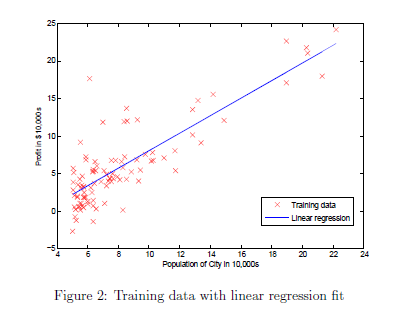    

    Your final values for $\theta$ will also be used to make predictions on profits in areas of 35,000 and 70,000 people.

% Run gradient descent:
% Compute theta
theta = gradientDescent(X, y, theta, alpha, iterations);

% Print theta to screen
% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta, '-')
legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this figure

% Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] *theta;
fprintf('For population = 35,000, we predict a profit of %f\n', predict1*10000);
predict2 = [1, 7] * theta;
fprintf('For population = 70,000, we predict a profit of %f\n', predict2*10000);

    Note the way that the lines above use matrix multiplication, rather than explicit summation or looping, to calculate the predictions. This is an example of *code vectorization* in MATLAB. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.3 Debugging

Here are some things to keep in mind as you implement gradient descent: 

- MATLAB array indices start from one, not zero. If you're storing $\theta_0$ and $\theta_1$ in a vector called `theta`, the values will be `theta(1)` and `theta(2)`.

- If you are seeing many errors at runtime, inspect your matrix operations to make sure that you're adding and multiplying matrices of compatible dimensions. Printing the dimensions of variables with the `size` command will help you debug.

- By default, MATLAB interprets math operators to be matrix operators. This is a common source of size incompatibility errors. If you don't want matrix multiplication, you need to add the "dot" notation to specify this to MATLAB. For example, `A*B` does a matrix multiply, while `A.*B` does an element-wise multiplication.

### 2.4 Visualizing $J(\theta)$

To understand the cost function $J(\theta)$ better, you will now plot the cost over a 2-dimensional grid of $\theta_0$ and $\theta_1$ values. You will not need to code anything new for this part, but you should understand how the code you have written already is creating these images.

    In the next step, there is code set up to calculate $J(\theta)$ over a grid of values using the `computeCost` function that you wrote. 

% Visualizing J(theta_0, theta_1):
% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];    
	  J_vals(i,j) = computeCost(X, y, t);
    end
end

    After the code above is executed, you will have a 2-D array of $J(\theta)$ values. The code below will then use these values to produce surface and contour plots of $J(\theta)$ using the `surf` and `contour` commands. Run the code in this section now. The resulting plots should look something like the figure below.

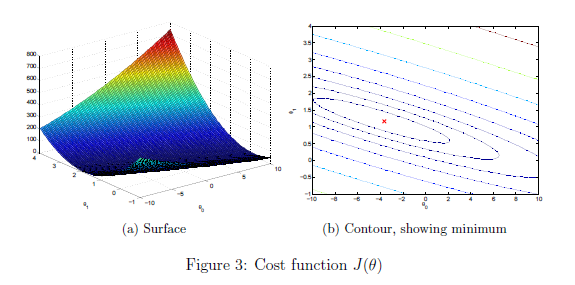

% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

    The purpose of these graphs is to show you that how $J(\theta)$ varies with changes in $\theta_0$ and $\theta_1$. The cost function $J(\theta)$ is bowl-shaped and has a global mininum. (This is easier to see in the contour plot than in the 3D surface plot). This minimum is the optimal point for $\theta_0$ and $\theta_1$, and each step of gradient descent moves closer to this point.

## Optional Exercises:

If you have successfully completed the material above, congratulations! You now understand linear regression and should able to start using it on your own datasets. For the rest of this programming exercise, we have included the following optional exercises. These exercises will help you gain a deeper understanding of the material, and if you are able to do so, we encourage you to complete them as well.

## 3. Linear regression with multiple variables

In this part, you will implement linear regression with multiple variables to predict the prices of houses. Suppose you are selling your house and you want to know what a good market price would be. One way to do this is to first collect information on recent houses sold and make a model of housing prices.

    The file `ex1data2.txt` contains a training set of housing prices in Portland, Oregon. The first column is the size of the house (in square feet), the second column is the number of bedrooms, and the third column is the price of the house. Run this section now to preview the data.

% Load Data
data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Print out some data points
% First 10 examples from the dataset
fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

 x = [2104 3], y = 399900 
 x = [1600 3], y = 329900 
 x = [2400 3], y = 369000 
 x = [1416 2], y = 232000 
 x = [3000 4], y = 539900 
 x = [1985 4], y = 299900 
 x = [1534 3], y = 314900 
 x = [1427 3], y = 198999 
 x = [1380 3], y = 212000 
 x = [1494 3], y = 242500 


The remainder of this script has been set up to help you step through this exercise.

### 3.1 Feature Normalization

This section of the script will start by loading and displaying some values from this dataset. By looking at the values, note that house sizes are about 1000 times the number of bedrooms. When features differ by orders of magnitude, first performing feature scaling can make gradient descent converge much more quickly.

    Your task here is to complete the code in `featureNormalize.m` to:

- Subtract the mean value of each feature from the dataset.

- After subtracting the mean, additionally scale (divide) the feature values by their respective "standard deviations".

The standard deviation is a way of measuring how much variation there is in the range of values of a particular feature (most data points will lie within $\pm 2$ standard deviations of the mean); this is an alternative to taking the range of values (*max - min*). In MATLAB, you can use the `std` function to compute the standard deviation. For example, inside `featureNormalize.m`, the quantity `X(:,1)` contains all the values of $x_1$ (house sizes) in the training set, so `std(X(:,1))` computes the standard deviation of the house sizes. At the time that `featureNormalize.m` is called, the extra column of 1's corresponding to $x_0 = 1$ has not yet been added to `X` (see the code below for details).

    You will do this for all the features and your code should work with datasets of all sizes (any number of features / examples). Note that each column of the matrix `X` corresponds to one feature. When you are finished with `featureNormailize.m`, run this section to normailze the features of the housing dataset.

% Scale features and set them to zero mean
[X, mu, sigma] = featureNormalize(X);

mu = 	1.0e+03 *

    2.0007    0.0032


sigma =   794.7024    0.7610


X_norm =     0.1300   -0.2237
   -0.5042   -0.2237
    0.5025   -0.2237
   -0.7357   -1.5378
    1.2575    1.0904
   -0.0197    1.0904
   -0.5872   -0.2237
   -0.7219   -0.2237
   -0.7810   -0.2237
   -0.6376   -0.2237


**Implementation Note: **When normalizing the features, it is important to store the values used for normalization - the mean value and the standard deviation used for the computations. After learning the parameters from the model, we often want to predict the prices of houses we have not seen before. Given a new `x` value (living room area and number of bedrooms), we must first normalize `x` using the mean and standard deviation that we had previously computed from the training set.

#### Add the bias term

Now that we have normailzed the features, we again add a column of ones corresponding to $\theta_0$ to the data matrix `X``.`

% Add intercept term to X
X = [ones(m, 1) X];

### 3.2 Gradient Descent

Previously, you implemented gradient descent on a univariate regression problem. The only difference now is that there is one more feature in the matrix `X`. The hypothesis function and the batch gradient descent update rule remain unchanged.

    You should complete the code in `computeCostMulti.m` and `gradientDescentMulti``.m `to implement the cost function and gradient descent for linear regression *with multiple variables*. If your code in the previous part (single variable) already supports multiple variables, you can use it here too.

Make sure your code supports any number of features and is well-vectorized. You can use the command `size(X,2)` to find out how many features are present in the dataset.

    We have provided you with the following starter code below that runs gradient descent with a particular learning rate (`alpha`). Your task is to first make sure that your functions `computeCost` and `gradientDescent` already work with this starter code and support multiple variables.  

**Implementation Note: **In the multivariate case, the cost function can also be written in the following vectorized form:


$$J(\theta)=\frac{1}{2m}\left(X\theta-\vec{y}\right)^T\left(X\theta-\vec{y}\right)$$


where


$$X=\left\lbrack \begin{array}{c}
{-\;\left(x^{\left(1\right)} \right)}^T -\\
{-\;\left(x^{\left(2\right)} \right)}^T -\\
\vdots \;\\
{-\;\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\vec{y} =\left\lbrack \begin{array}{c}
y^{\left(1\right)} \\
y^{\left(2\right)} \\
\vdots \;\\
y^{\left(m\right)} 
\end{array}\right\rbrack$$


The vectorized version is efficient when you're working with numerical computing tools like MATLAB. If you are an expert with matrix operations, you can prove to yourself that the two forms are equivalent.

% Run gradient descent
% Choose some alpha value
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

delta = 	1.0e+05 *

   -3.4041
   -1.0463
   -0.5412


theta = 	1.0e+04 *

    3.4041
    1.0463
    0.5412


J = 5.3294e+10

delta = 	1.0e+05 *

   -3.0637
   -0.9143
   -0.4309


theta = 	1.0e+04 *

    6.4678
    1.9606
    0.9722


J = 4.3427e+10

delta = 	1.0e+05 *

   -2.7573
   -0.8012
   -0.3386


theta = 	1.0e+04 *

    9.2252
    2.7618
    1.3108


J = 3.5500e+10

delta = 	1.0e+05 *

   -2.4816
   -0.7042
   -0.2616


theta = 	1.0e+05 *

    1.1707
    0.3466
    0.1572


J = 2.9123e+10

delta = 	1.0e+05 *

   -2.2334
   -0.6209
   -0.1974


theta = 	1.0e+05 *

    1.3940
    0.4087
    0.1770


J = 2.3987e+10

delta = 	1.0e+05 *

   -2.0101
   -0.5493
   -0.1440


theta = 	1.0e+05 *

    1.5950
    0.4636
    0.1914


J = 1.9846e+10

delta = 	1.0e+05 *

   -1.8091
   -0.4877
   -0.0998


theta = 	1.0e+05 *

    1.7759
    0.5124
    0.2014


J = 1.6504e+10

delta = 	1.0e+05 *

   -1.6282
   -0.4345
   -0.0633


theta = 	1.0e+05 *

    1.9388
    0.5558
    0.2077


J = 1.3803e+10

delta = 	1.0e+05 *

   -1.4654
   -0.3885
   -0.0333


theta = 	1.0e+05 *

    2.0853
    0.5947
    0.2110


J = 1.1620e+10

delta = 	1.0e+05 *

   -1.3188
   -0.3486
   -0.0088


theta = 	1.0e+05 *

    2.2172
    0.6296
    0.2119


J = 9.8517e+09

delta = 	1.0e+05 *

   -1.1869
   -0.3140
    0.0112


theta = 	1.0e+05 *

    2.3359
    0.6610
    0.2108


J = 8.4192e+09

delta = 	1.0e+05 *

   -1.0683
   -0.2839
    0.0273


theta = 	1.0e+05 *

    2.4427
    0.6893
    0.2081


J = 7.2573e+09

delta = 	1.0e+04 *

   -9.6143
   -2.5762
    0.4019


theta = 	1.0e+05 *

    2.5388
    0.7151
    0.2040


J = 6.3139e+09

delta = 	1.0e+04 *

   -8.6528
   -2.3461
    0.5038


theta = 	1.0e+05 *

    2.6254
    0.7386
    0.1990


J = 5.5472e+09

delta = 	1.0e+04 *

   -7.7875
   -2.1441
    0.5831


theta = 	1.0e+05 *

    2.7032
    0.7600
    0.1932


J = 4.9234e+09

delta = 	1.0e+04 *

   -7.0088
   -1.9662
    0.6435


theta = 	1.0e+05 *

    2.7733
    0.7797
    0.1867


J = 4.4154e+09

delta = 	1.0e+04 *

   -6.3079
   -1.8090
    0.6883


theta = 	1.0e+05 *

    2.8364
    0.7978
    0.1799


J = 4.0011e+09

delta = 	1.0e+04 *

   -5.6771
   -1.6697
    0.7201


theta = 	1.0e+05 *

    2.8932
    0.8145
    0.1727


J = 3.6628e+09

delta = 	1.0e+04 *

   -5.1094
   -1.5458
    0.7411


theta = 	1.0e+05 *

    2.9443
    0.8299
    0.1652


J = 3.3862e+09

delta = 	1.0e+04 *

   -4.5985
   -1.4351
    0.7533


theta = 	1.0e+05 *

    2.9903
    0.8443
    0.1577


J = 3.1597e+09

delta = 	1.0e+04 *

   -4.1386
   -1.3359
    0.7582


theta = 	1.0e+05 *

    3.0317
    0.8576
    0.1501


J = 2.9740e+09

delta = 	1.0e+04 *

   -3.7248
   -1.2467
    0.7572


theta = 	1.0e+05 *

    3.0689
    0.8701
    0.1426


J = 2.8215e+09

delta = 	1.0e+04 *

   -3.3523
   -1.1662
    0.7514


theta = 	1.0e+05 *

    3.1024
    0.8818
    0.1350


J = 2.6959e+09

delta = 	1.0e+04 *

   -3.0171
   -1.0932
    0.7418


theta = 	1.0e+05 *

    3.1326
    0.8927
    0.1276


J = 2.5924e+09

delta = 	1.0e+04 *

   -2.7154
   -1.0269
    0.7291


theta = 	1.0e+05 *

    3.1597
    0.9030
    0.1203


J = 2.5068e+09

delta = 3×1
   -2.4438
   -0.9664
    0.7140


theta = 3×1
    3.1842
    0.9126
    0.1132


J = 2.4360e+09

delta = 3×1
   -2.1994
   -0.9109
    0.6971


theta = 3×1
    3.2062
    0.9217
    0.1062


J = 2.3772e+09

delta = 3×1
   -1.9795
   -0.8600
    0.6788


theta = 3×1
    3.2260
    0.9303
    0.0994


J = 2.3282e+09

delta = 3×1
   -1.7815
   -0.8130
    0.6595


theta = 3×1
    3.2438
    0.9385
    0.0928


J = 2.2874e+09

delta = 3×1
   -1.6034
   -0.7696
    0.6395


theta = 3×1
    3.2598
    0.9462
    0.0864


J = 2.2531e+09

delta = 3×1
   -1.4430
   -0.7293
    0.6191


theta = 3×1
    3.2743
    0.9534
    0.0803


J = 2.2244e+09

delta = 3×1
   -1.2987
   -0.6918
    0.5985


theta = 3×1
    3.2872
    0.9604
    0.0743


J = 2.2002e+09

delta = 3×1
   -1.1689
   -0.6569
    0.5778


theta = 3×1
    3.2989
    0.9669
    0.0685


J = 2.1797e+09

delta = 3×1
   -1.0520
   -0.6243
    0.5573


theta = 3×1
    3.3094
    0.9732
    0.0629


J = 2.1624e+09

delta = 3×1
   -9.4678
   -5.9375
    5.3694


theta = 3×1
    3.3189
    0.9791
    0.0575


J = 2.1476e+09

delta = 3×1
   -8.5211
   -5.6506
    5.1693


theta = 3×1
    3.3274
    0.9848
    0.0524


J = 2.1349e+09

delta = 3×1
   -7.6690
   -5.3809
    4.9731


theta = 3×1
    3.3351
    0.9901
    0.0474


J = 2.1241e+09

delta = 3×1
   -6.9021
   -5.1268
    4.7812


theta = 3×1
    3.3420
    0.9953
    0.0426


J = 2.1148e+09

delta = 3×1
   -6.2119
   -4.8871
    4.5943


theta = 3×1
    3.3482
    1.0002
    0.0380


J = 2.1067e+09

delta = 3×1
   -5.5907
   -4.6605
    4.4124


theta = 3×1
    3.3538
    1.0048
    0.0336


J = 2.0997e+09

delta = 3×1
   -5.0316
   -4.4462
    4.2360


theta = 3×1
    3.3588
    1.0093
    0.0294


J = 2.0936e+09

delta = 3×1
   -4.5284
   -4.2432
    4.0651


theta = 3×1
    3.3634
    1.0135
    0.0253


J = 2.0883e+09

delta = 3×1
   -4.0756
   -4.0507
    3.8998


theta = 3×1
    3.3674
    1.0176
    0.0214


J = 2.0836e+09

delta = 3×1
   -3.6680
   -3.8680
    3.7401


theta = 3×1
    3.3711
    1.0214
    0.0177


J = 2.0795e+09

delta = 3×1
   -3.3012
   -3.6944
    3.5860


theta = 3×1
    3.3744
    1.0251
    0.0141


J = 2.0759e+09

delta = 3×1
   -2.9711
   -3.5294
    3.4375


theta = 3×1
    3.3774
    1.0287
    0.0107


J = 2.0727e+09

delta = 3×1
   -2.6740
   -3.3723
    3.2945


theta = 3×1
    3.3801
    1.0320
    0.0074


J = 2.0698e+09

delta = 3×1
   -2.4066
   -3.2228
    3.1569


theta = 3×1
    3.3825
    1.0353
    0.0042


J = 2.0673e+09

delta = 3×1
   -2.1659
   -3.0804
    3.0246


theta = 3×1
    3.3846
    1.0383
    0.0012


J = 2.0650e+09

delta = 3×1
   -1.9493
   -2.9447
    2.8974


theta = 3×1
    3.3866
    1.0413
   -0.0017


J = 2.0630e+09

delta = 3×1
   -1.7544
   -2.8153
    2.7752


theta = 3×1
    3.3883
    1.0441
   -0.0045


J = 2.0611e+09

delta = 3×1
   -1.5790
   -2.6918
    2.6579


theta = 3×1
    3.3899
    1.0468
   -0.0072


J = 2.0595e+09

delta = 3×1
   -1.4211
   -2.5740
    2.5452


theta = 3×1
    3.3913
    1.0494
   -0.0097


J = 2.0580e+09

delta = 3×1
   -1.2790
   -2.4616
    2.4372


theta = 3×1
    3.3926
    1.0518
   -0.0121


J = 2.0567e+09

delta = 3×1
   -1.1511
   -2.3543
    2.3336


theta = 3×1
    3.3938
    1.0542
   -0.0145


J = 2.0555e+09

delta = 3×1
   -1.0360
   -2.2517
    2.2342


theta = 3×1
    3.3948
    1.0564
   -0.0167


J = 2.0544e+09

delta = 3×1
   -0.9324
   -2.1538
    2.1390


theta = 3×1
    3.3957
    1.0586
   -0.0188


J = 2.0534e+09

delta = 3×1
   -0.8391
   -2.0602
    2.0476


theta = 3×1
    3.3966
    1.0606
   -0.0209


J = 2.0525e+09

delta = 3×1
   -0.7552
   -1.9708
    1.9602


theta = 3×1
    3.3973
    1.0626
   -0.0229


J = 2.0517e+09

delta = 3×1
   -0.6797
   -1.8853
    1.8763


theta = 3×1
    3.3980
    1.0645
   -0.0247


J = 2.0510e+09

delta = 3×1
   -0.6117
   -1.8037
    1.7960


theta = 3×1
    3.3986
    1.0663
   -0.0265


J = 2.0503e+09

delta = 3×1
   -0.5506
   -1.7256
    1.7191


theta = 3×1
    3.3992
    1.0680
   -0.0282


J = 2.0497e+09

delta = 3×1
   -0.4955
   -1.6509
    1.6454


theta = 3×1
    3.3997
    1.0697
   -0.0299


J = 2.0492e+09

delta = 3×1
   -0.4459
   -1.5795
    1.5748


theta = 3×1
    3.4001
    1.0713
   -0.0315


J = 2.0486e+09

delta = 3×1
   -0.4014
   -1.5112
    1.5073


theta = 3×1
    3.4005
    1.0728
   -0.0330


J = 2.0482e+09

delta = 3×1
   -0.3612
   -1.4459
    1.4426


theta = 3×1
    3.4009
    1.0742
   -0.0344


J = 2.0478e+09

delta = 3×1
   -0.3251
   -1.3835
    1.3806


theta = 3×1
    3.4012
    1.0756
   -0.0358


J = 2.0474e+09

delta = 3×1
   -0.2926
   -1.3237
    1.3213


theta = 3×1
    3.4015
    1.0769
   -0.0371


J = 2.0470e+09

delta = 3×1
   -0.2633
   -1.2666
    1.2645


theta = 3×1
    3.4018
    1.0782
   -0.0384


J = 2.0467e+09

delta = 3×1
   -0.2370
   -1.2119
    1.2102


theta = 3×1
    3.4020
    1.0794
   -0.0396


J = 2.0464e+09

delta = 3×1
   -0.2133
   -1.1596
    1.1582


theta = 3×1
    3.4022
    1.0806
   -0.0407


J = 2.0462e+09

delta = 3×1
   -0.1920
   -1.1096
    1.1084


theta = 3×1
    3.4024
    1.0817
   -0.0419


J = 2.0459e+09

delta = 3×1
   -0.1728
   -1.0618
    1.0607


theta = 3×1
    3.4026
    1.0827
   -0.0429


J = 2.0457e+09

delta = 3×1
   -0.1555
   -1.0160
    1.0151


theta = 3×1
    3.4027
    1.0837
   -0.0439


J = 2.0455e+09

delta = 3×1
 -139.9431
 -972.1672
  971.4150


theta = 3×1
    3.4029
    1.0847
   -0.0449


J = 2.0453e+09

delta = 3×1
 -125.9488
 -930.2576
  929.6203


theta = 3×1
    3.4030
    1.0856
   -0.0458


J = 2.0451e+09

delta = 3×1
 -113.3539
 -890.1593
  889.6192


theta = 3×1
    3.4031
    1.0865
   -0.0467


J = 2.0450e+09

delta = 3×1
 -102.0185
 -851.7931
  851.3356


theta = 3×1
    3.4032
    1.0874
   -0.0476


J = 2.0448e+09

delta = 3×1
  -91.8166
 -815.0839
  814.6961


theta = 3×1
    3.4033
    1.0882
   -0.0484


J = 2.0447e+09

delta = 3×1
  -82.6350
 -779.9594
  779.6308


theta = 3×1
    3.4034
    1.0890
   -0.0492


J = 2.0446e+09

delta = 3×1
  -74.3715
 -746.3508
  746.0724


theta = 3×1
    3.4035
    1.0897
   -0.0499


J = 2.0445e+09

delta = 3×1
  -66.9343
 -714.1924
  713.9566


theta = 3×1
    3.4035
    1.0904
   -0.0506


J = 2.0444e+09

delta = 3×1
  -60.2409
 -683.4214
  683.2215


theta = 3×1
    3.4036
    1.0911
   -0.0513


J = 2.0443e+09

delta = 3×1
  -54.2168
 -653.9775
  653.8081


theta = 3×1
    3.4036
    1.0918
   -0.0520


J = 2.0442e+09

delta = 3×1
  -48.7951
 -625.8033
  625.6598


theta = 3×1
    3.4037
    1.0924
   -0.0526


J = 2.0441e+09

delta = 3×1
  -43.9156
 -598.8440
  598.7224


theta = 3×1
    3.4037
    1.0930
   -0.0532


J = 2.0440e+09

delta = 3×1
  -39.5241
 -573.0469
  572.9438


theta = 3×1
    3.4038
    1.0936
   -0.0538


J = 2.0440e+09

delta = 3×1
  -35.5717
 -548.3618
  548.2745


theta = 3×1
    3.4038
    1.0941
   -0.0543


J = 2.0439e+09

delta = 3×1
  -32.0145
 -524.7407
  524.6667


theta = 3×1
    3.4038
    1.0947
   -0.0548


J = 2.0439e+09

delta = 3×1
  -28.8130
 -502.1376
  502.0749


theta = 3×1
    3.4039
    1.0952
   -0.0553


J = 2.0438e+09

delta = 3×1
  -25.9317
 -480.5086
  480.4555


theta = 3×1
    3.4039
    1.0956
   -0.0558


J = 2.0438e+09

delta = 3×1
  -23.3386
 -459.8116
  459.7666


theta = 3×1
    3.4039
    1.0961
   -0.0563


J = 2.0437e+09

delta = 3×1
  -21.0047
 -440.0064
  439.9683


theta = 3×1
    3.4039
    1.0965
   -0.0567


J = 2.0437e+09

delta = 3×1
  -18.9042
 -421.0545
  421.0222


theta = 3×1
    3.4040
    1.0970
   -0.0571


J = 2.0437e+09

delta = 3×1
  -17.0138
 -402.9192
  402.8918


theta = 3×1
    3.4040
    1.0974
   -0.0575


J = 2.0436e+09

delta = 3×1
  -15.3124
 -385.5652
  385.5420


theta = 3×1
    3.4040
    1.0977
   -0.0579


J = 2.0436e+09

delta = 3×1
  -13.7812
 -368.9587
  368.9391


theta = 3×1
    3.4040
    1.0981
   -0.0583


J = 2.0436e+09

delta = 3×1
  -12.4031
 -353.0677
  353.0510


theta = 3×1
    3.4040
    1.0985
   -0.0586


J = 2.0435e+09

delta = 3×1
  -11.1628
 -337.8612
  337.8471


theta = 3×1
    3.4040
    1.0988
   -0.0590


J = 2.0435e+09

delta = 3×1
  -10.0465
 -323.3097
  323.2978


theta = 3×1
    3.4040
    1.0991
   -0.0593


J = 2.0435e+09

delta = 3×1
   -9.0418
 -309.3851
  309.3750


theta = 3×1
    3.4040
    1.0994
   -0.0596


J = 2.0435e+09

delta = 3×1
   -8.1377
 -296.0602
  296.0517


theta = 3×1
    3.4041
    1.0997
   -0.0599


J = 2.0435e+09

delta = 3×1
   -7.3239
 -283.3093
  283.3021


theta = 3×1
    3.4041
    1.1000
   -0.0602


J = 2.0435e+09

delta = 3×1
   -6.5915
 -271.1076
  271.1015


theta = 3×1
    3.4041
    1.1003
   -0.0605


J = 2.0434e+09

delta = 3×1
   -5.9323
 -259.4315
  259.4263


theta = 3×1
    3.4041
    1.1005
   -0.0607


J = 2.0434e+09

delta = 3×1
   -5.3391
 -248.2583
  248.2538


theta = 3×1
    3.4041
    1.1008
   -0.0610


J = 2.0434e+09

delta = 3×1
   -4.8052
 -237.5663
  237.5625


theta = 3×1
    3.4041
    1.1010
   -0.0612


J = 2.0434e+09

delta = 3×1
   -4.3247
 -227.3348
  227.3316


theta = 3×1
    3.4041
    1.1013
   -0.0614


J = 2.0434e+09

delta = 3×1
   -3.8922
 -217.5440
  217.5413


theta = 3×1
    3.4041
    1.1015
   -0.0617


J = 2.0434e+09

delta = 3×1
   -3.5030
 -208.1749
  208.1726


theta = 3×1
    3.4041
    1.1017
   -0.0619


J = 2.0434e+09

delta = 3×1
   -3.1527
 -199.2093
  199.2073


theta = 3×1
    3.4041
    1.1019
   -0.0621


J = 2.0434e+09

delta = 3×1
   -2.8374
 -190.6298
  190.6282


theta = 3×1
    3.4041
    1.1021
   -0.0623


J = 2.0434e+09

delta = 3×1
   -2.5537
 -182.4199
  182.4185


theta = 3×1
    3.4041
    1.1023
   -0.0624


J = 2.0434e+09

delta = 3×1
   -2.2983
 -174.5635
  174.5623


theta = 3×1
    3.4041
    1.1024
   -0.0626


J = 2.0433e+09

delta = 3×1
   -2.0685
 -167.0455
  167.0445


theta = 3×1
    3.4041
    1.1026
   -0.0628


J = 2.0433e+09

delta = 3×1
   -1.8616
 -159.8513
  159.8504


theta = 3×1
    3.4041
    1.1028
   -0.0629


J = 2.0433e+09

delta = 3×1
   -1.6755
 -152.9669
  152.9662


theta = 3×1
    3.4041
    1.1029
   -0.0631


J = 2.0433e+09

delta = 3×1
   -1.5079
 -146.3790
  146.3784


theta = 3×1
    3.4041
    1.1031
   -0.0632


J = 2.0433e+09

delta = 3×1
   -1.3571
 -140.0749
  140.0744


theta = 3×1
    3.4041
    1.1032
   -0.0634


J = 2.0433e+09

delta = 3×1
   -1.2214
 -134.0423
  134.0418


theta = 3×1
    3.4041
    1.1033
   -0.0635


J = 2.0433e+09

delta = 3×1
   -1.0993
 -128.2694
  128.2691


theta = 3×1
    3.4041
    1.1035
   -0.0636


J = 2.0433e+09

delta = 3×1
   -0.9893
 -122.7452
  122.7449


theta = 3×1
    3.4041
    1.1036
   -0.0638


J = 2.0433e+09

delta = 3×1
   -0.8904
 -117.4589
  117.4587


theta = 3×1
    3.4041
    1.1037
   -0.0639


J = 2.0433e+09

delta = 3×1
   -0.8014
 -112.4003
  112.4001


theta = 3×1
    3.4041
    1.1038
   -0.0640


J = 2.0433e+09

delta = 3×1
   -0.7212
 -107.5596
  107.5594


theta = 3×1
    3.4041
    1.1039
   -0.0641


J = 2.0433e+09

delta = 3×1
   -0.6491
 -102.9273
  102.9271


theta = 3×1
    3.4041
    1.1040
   -0.0642


J = 2.0433e+09

delta = 3×1
   -0.5842
  -98.4945
   98.4944


theta = 3×1
    3.4041
    1.1041
   -0.0643


J = 2.0433e+09

delta = 3×1
   -0.5258
  -94.2526
   94.2525


theta = 3×1
    3.4041
    1.1042
   -0.0644


J = 2.0433e+09

delta = 3×1
   -0.4732
  -90.1934
   90.1933


theta = 3×1
    3.4041
    1.1043
   -0.0645


J = 2.0433e+09

delta = 3×1
   -0.4259
  -86.3091
   86.3090


theta = 3×1
    3.4041
    1.1044
   -0.0646


J = 2.0433e+09

delta = 3×1
   -0.3833
  -82.5920
   82.5919


theta = 3×1
    3.4041
    1.1045
   -0.0647


J = 2.0433e+09

delta = 3×1
   -0.3450
  -79.0350
   79.0349


theta = 3×1
    3.4041
    1.1046
   -0.0647


J = 2.0433e+09

delta = 3×1
   -0.3105
  -75.6312
   75.6311


theta = 3×1
    3.4041
    1.1046
   -0.0648


J = 2.0433e+09

delta = 3×1
   -0.2794
  -72.3740
   72.3739


theta = 3×1
    3.4041
    1.1047
   -0.0649


J = 2.0433e+09

delta = 3×1
   -0.2515
  -69.2570
   69.2570


theta = 3×1
    3.4041
    1.1048
   -0.0650


J = 2.0433e+09

delta = 3×1
   -0.2263
  -66.2743
   66.2743


theta = 3×1
    3.4041
    1.1048
   -0.0650


J = 2.0433e+09

delta = 3×1
   -0.2037
  -63.4201
   63.4201


theta = 3×1
    3.4041
    1.1049
   -0.0651


J = 2.0433e+09

delta = 3×1
   -0.1833
  -60.6888
   60.6888


theta = 3×1
    3.4041
    1.1050
   -0.0651


J = 2.0433e+09

delta = 3×1
   -0.1650
  -58.0751
   58.0751


theta = 3×1
    3.4041
    1.1050
   -0.0652


J = 2.0433e+09

delta = 3×1
   -0.1485
  -55.5740
   55.5739


theta = 3×1
    3.4041
    1.1051
   -0.0653


J = 2.0433e+09

delta = 3×1
   -0.1336
  -53.1806
   53.1805


theta = 3×1
    3.4041
    1.1051
   -0.0653


J = 2.0433e+09

delta = 3×1
   -0.1203
  -50.8902
   50.8902


theta = 3×1
    3.4041
    1.1052
   -0.0654


J = 2.0433e+09

delta = 3×1
   -0.1083
  -48.6985
   48.6985


theta = 3×1
    3.4041
    1.1052
   -0.0654


J = 2.0433e+09

delta = 3×1
   -0.0974
  -46.6012
   46.6012


theta = 3×1
    3.4041
    1.1053
   -0.0655


J = 2.0433e+09

delta = 3×1
   -0.0877
  -44.5943
   44.5942


theta = 3×1
    3.4041
    1.1053
   -0.0655


J = 2.0433e+09

delta = 3×1
   -0.0789
  -42.6737
   42.6737


theta = 3×1
    3.4041
    1.1054
   -0.0655


J = 2.0433e+09

delta = 3×1
   -0.0710
  -40.8359
   40.8359


theta = 3×1
    3.4041
    1.1054
   -0.0656


J = 2.0433e+09

delta = 3×1
   -0.0639
  -39.0772
   39.0772


theta = 3×1
    3.4041
    1.1054
   -0.0656


J = 2.0433e+09

delta = 3×1
   -0.0575
  -37.3943
   37.3943


theta = 3×1
    3.4041
    1.1055
   -0.0657


J = 2.0433e+09

delta = 3×1
   -0.0518
  -35.7838
   35.7838


theta = 3×1
    3.4041
    1.1055
   -0.0657


J = 2.0433e+09

delta = 3×1
   -0.0466
  -34.2427
   34.2427


theta = 3×1
    3.4041
    1.1055
   -0.0657


J = 2.0433e+09

delta = 3×1
   -0.0419
  -32.7680
   32.7680


theta = 3×1
    3.4041
    1.1056
   -0.0658


J = 2.0433e+09

delta = 3×1
   -0.0377
  -31.3567
   31.3567


theta = 3×1
    3.4041
    1.1056
   -0.0658


J = 2.0433e+09

delta = 3×1
   -0.0340
  -30.0063
   30.0063


theta = 3×1
    3.4041
    1.1056
   -0.0658


J = 2.0433e+09

delta = 3×1
   -0.0306
  -28.7140
   28.7140


theta = 3×1
    3.4041
    1.1057
   -0.0659


J = 2.0433e+09

delta = 3×1
   -0.0275
  -27.4774
   27.4774


theta = 3×1
    3.4041
    1.1057
   -0.0659


J = 2.0433e+09

delta = 3×1
   -0.0248
  -26.2940
   26.2940


theta = 3×1
    3.4041
    1.1057
   -0.0659


J = 2.0433e+09

delta = 3×1
   -0.0223
  -25.1616
   25.1616


theta = 3×1
    3.4041
    1.1058
   -0.0659


J = 2.0433e+09

delta = 3×1
   -0.0201
  -24.0780
   24.0780


theta = 3×1
    3.4041
    1.1058
   -0.0660


J = 2.0433e+09

delta = 3×1
   -0.0181
  -23.0410
   23.0410


theta = 3×1
    3.4041
    1.1058
   -0.0660


J = 2.0433e+09

delta = 3×1
   -0.0162
  -22.0487
   22.0487


theta = 3×1
    3.4041
    1.1058
   -0.0660


J = 2.0433e+09

delta = 3×1
   -0.0146
  -21.0991
   21.0991


theta = 3×1
    3.4041
    1.1058
   -0.0660


J = 2.0433e+09

delta = 3×1
   -0.0132
  -20.1905
   20.1905


theta = 3×1
    3.4041
    1.1059
   -0.0660


J = 2.0433e+09

delta = 3×1
   -0.0118
  -19.3209
   19.3209


theta = 3×1
    3.4041
    1.1059
   -0.0661


J = 2.0433e+09

delta = 3×1
   -0.0107
  -18.4888
   18.4888


theta = 3×1
    3.4041
    1.1059
   -0.0661


J = 2.0433e+09

delta = 3×1
   -0.0096
  -17.6926
   17.6926


theta = 3×1
    3.4041
    1.1059
   -0.0661


J = 2.0433e+09

delta = 3×1
   -0.0086
  -16.9306
   16.9306


theta = 3×1
    3.4041
    1.1059
   -0.0661


J = 2.0433e+09

delta = 3×1
   -0.0078
  -16.2014
   16.2014


theta = 3×1
    3.4041
    1.1060
   -0.0661


J = 2.0433e+09

delta = 3×1
   -0.0070
  -15.5037
   15.5037


theta = 3×1
    3.4041
    1.1060
   -0.0662


J = 2.0433e+09

delta = 3×1
   -0.0063
  -14.8360
   14.8360


theta = 3×1
    3.4041
    1.1060
   -0.0662


J = 2.0433e+09

delta = 3×1
   -0.0057
  -14.1971
   14.1971


theta = 3×1
    3.4041
    1.1060
   -0.0662


J = 2.0433e+09

delta = 3×1
   -0.0051
  -13.5856
   13.5856


theta = 3×1
    3.4041
    1.1060
   -0.0662


J = 2.0433e+09

delta = 3×1
   -0.0046
  -13.0005
   13.0005


theta = 3×1
    3.4041
    1.1060
   -0.0662


J = 2.0433e+09

delta = 3×1
   -0.0041
  -12.4406
   12.4406


theta = 3×1
    3.4041
    1.1060
   -0.0662


J = 2.0433e+09

delta = 3×1
   -0.0037
  -11.9049
   11.9049


theta = 3×1
    3.4041
    1.1060
   -0.0662


J = 2.0433e+09

delta = 3×1
   -0.0033
  -11.3922
   11.3922


theta = 3×1
    3.4041
    1.1061
   -0.0662


J = 2.0433e+09

delta = 3×1
   -0.0030
  -10.9015
   10.9015


theta = 3×1
    3.4041
    1.1061
   -0.0663


J = 2.0433e+09

delta = 3×1
   -0.0027
  -10.4320
   10.4320


theta = 3×1
    3.4041
    1.1061
   -0.0663


J = 2.0433e+09

delta = 3×1
   -0.0024
   -9.9828
    9.9828


theta = 3×1
    3.4041
    1.1061
   -0.0663


J = 2.0433e+09

delta = 3×1
   -0.0022
   -9.5528
    9.5528


theta = 3×1
    3.4041
    1.1061
   -0.0663


J = 2.0433e+09

delta = 3×1
   -0.0020
   -9.1414
    9.1414


theta = 3×1
    3.4041
    1.1061
   -0.0663


J = 2.0433e+09

delta = 3×1
   -0.0018
   -8.7477
    8.7477


theta = 3×1
    3.4041
    1.1061
   -0.0663


J = 2.0433e+09

delta = 3×1
   -0.0016
   -8.3710
    8.3710


theta = 3×1
    3.4041
    1.1061
   -0.0663


J = 2.0433e+09

delta = 3×1
   -0.0014
   -8.0105
    8.0105


theta = 3×1
    3.4041
    1.1061
   -0.0663


J = 2.0433e+09

delta = 3×1
   -0.0013
   -7.6655
    7.6655


theta = 3×1
    3.4041
    1.1061
   -0.0663


J = 2.0433e+09

delta = 3×1
   -0.0012
   -7.3354
    7.3354


theta = 3×1
    3.4041
    1.1061
   -0.0663


J = 2.0433e+09

delta = 3×1
   -0.0010
   -7.0194
    7.0194


theta = 3×1
    3.4041
    1.1062
   -0.0663


J = 2.0433e+09

delta = 3×1
   -0.0009
   -6.7171
    6.7171


theta = 3×1
    3.4041
    1.1062
   -0.0663


J = 2.0433e+09

delta = 3×1
   -0.0009
   -6.4278
    6.4278


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0008
   -6.1510
    6.1510


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0007
   -5.8861
    5.8861


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0006
   -5.6326
    5.6326


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0006
   -5.3900
    5.3900


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0005
   -5.1579
    5.1579


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0005
   -4.9358
    4.9358


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0004
   -4.7232
    4.7232


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0004
   -4.5198
    4.5198


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0003
   -4.3251
    4.3251


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0003
   -4.1389
    4.1389


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0003
   -3.9606
    3.9606


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0002
   -3.7900
    3.7900


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0002
   -3.6268
    3.6268


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0002
   -3.4706
    3.4706


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0002
   -3.3211
    3.3211


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0002
   -3.1781
    3.1781


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0001
   -3.0412
    3.0412


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0001
   -2.9103
    2.9103


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0001
   -2.7849
    2.7849


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0001
   -2.6650
    2.6650


theta = 3×1
    3.4041
    1.1063
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0001
   -2.5502
    2.5502


theta = 3×1
    3.4041
    1.1063
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0001
   -2.4404
    2.4404


theta = 3×1
    3.4041
    1.1063
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0001
   -2.3353
    2.3353


theta = 3×1
    3.4041
    1.1063
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0001
   -2.2347
    2.2347


theta = 3×1
    3.4041
    1.1063
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0001
   -2.1385
    2.1385


theta = 3×1
    3.4041
    1.1063
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0001
   -2.0464
    2.0464


theta = 3×1
    3.4041
    1.1063
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.9582
    1.9582


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.8739
    1.8739


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.7932
    1.7932


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.7160
    1.7160


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.6421
    1.6421


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.5714
    1.5714


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.5037
    1.5037


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.4389
    1.4389


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.3770
    1.3770


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.3176
    1.3176


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.2609
    1.2609


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.2066
    1.2066


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.1546
    1.1546


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.1049
    1.1049


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.0573
    1.0573


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.0118
    1.0118


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.9682
    0.9682


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.9265
    0.9265


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.8866
    0.8866


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.8484
    0.8484


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.8119
    0.8119


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.7769
    0.7769


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.7435
    0.7435


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.7114
    0.7114


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.6808
    0.6808


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.6515
    0.6515


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.6234
    0.6234


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.5966
    0.5966


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.5709
    0.5709


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.5463
    0.5463


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.5228
    0.5228


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.5003
    0.5003


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.4787
    0.4787


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.4581
    0.4581


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.4384
    0.4384


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.4195
    0.4195


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.4014
    0.4014


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.3841
    0.3841


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.3676
    0.3676


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.3518
    0.3518


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.3366
    0.3366


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.3221
    0.3221


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.3082
    0.3082


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.2950
    0.2950


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.2823
    0.2823


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.2701
    0.2701


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.2585
    0.2585


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.2473
    0.2473


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.2367
    0.2367


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.2265
    0.2265


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.2167
    0.2167


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.2074
    0.2074


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.1985
    0.1985


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.1899
    0.1899


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.1817
    0.1817


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.1739
    0.1739


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.1664
    0.1664


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.1593
    0.1593


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.1524
    0.1524


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.1458
    0.1458


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.1396
    0.1396


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.1335
    0.1335


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.1278
    0.1278


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.1223
    0.1223


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.1170
    0.1170


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.1120
    0.1120


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.1072
    0.1072


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.1025
    0.1025


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0981
    0.0981


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0939
    0.0939


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0899
    0.0899


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0860
    0.0860


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0823
    0.0823


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0787
    0.0787


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0754
    0.0754


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0721
    0.0721


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0690
    0.0690


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0660
    0.0660


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0632
    0.0632


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0605
    0.0605


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0579
    0.0579


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0554
    0.0554


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0530
    0.0530


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0507
    0.0507


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0485
    0.0485


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0464
    0.0464


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0444
    0.0444


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0425
    0.0425


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0407
    0.0407


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0389
    0.0389


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0373
    0.0373


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0357
    0.0357


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0341
    0.0341


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0326
    0.0326


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0312
    0.0312


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0299
    0.0299


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0286
    0.0286


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0274
    0.0274


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0262
    0.0262


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0251
    0.0251


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0240
    0.0240


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0230
    0.0230


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0220
    0.0220


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0210
    0.0210


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0201
    0.0201


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0192
    0.0192


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0184
    0.0184


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0176
    0.0176


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0169
    0.0169


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0161
    0.0161


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0154
    0.0154


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0148
    0.0148


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0141
    0.0141


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0135
    0.0135


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0130
    0.0130


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0124
    0.0124


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0119
    0.0119


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0114
    0.0114


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0109
    0.0109


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0104
    0.0104


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0099
    0.0099


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0095
    0.0095


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0091
    0.0091


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0087
    0.0087


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0083
    0.0083


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0080
    0.0080


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0076
    0.0076


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0073
    0.0073


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0070
    0.0070


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0067
    0.0067


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0064
    0.0064


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0061
    0.0061


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0059
    0.0059


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0056
    0.0056


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0054
    0.0054


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0051
    0.0051


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0049
    0.0049


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0047
    0.0047


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0045
    0.0045


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0043
    0.0043


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0041
    0.0041


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0039
    0.0039


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0038
    0.0038


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0036
    0.0036


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0035
    0.0035


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0033
    0.0033


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0032
    0.0032


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0030
    0.0030


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0029
    0.0029


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0028
    0.0028


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0027
    0.0027


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0025
    0.0025


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0024
    0.0024


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0023
    0.0023


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0022
    0.0022


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0021
    0.0021


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0020
    0.0020


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0020
    0.0020


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0019
    0.0019


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0018
    0.0018


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0017
    0.0017


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0016
    0.0016


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0016
    0.0016


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0015
    0.0015


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0014
    0.0014


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0014
    0.0014


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0013
    0.0013


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0013
    0.0013


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0012
    0.0012


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0012
    0.0012


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0011
    0.0011


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0011
    0.0011


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.0010
    0.0010


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.9646
    0.9646


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.9231
    0.9231


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.8833
    0.8833


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.8453
    0.8453


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.8089
    0.8089


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.7741
    0.7741


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.7407
    0.7407


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.7088
    0.7088


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.6783
    0.6783


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.6491
    0.6491


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.6211
    0.6211


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.5944
    0.5944


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09


% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

Theta computed from gradient descent:
340412.659574
110631.048958
-6649.472950

Finally, you should complete and run the code below to predict the price of a 1650 sq-ft, 3 br house using the value of `theta` obtained above. 

**Hint:** At prediction, make sure you do the same feature normalization. Recall that the first column of `X` is all ones. Thus, it does not need to be normalized.

% Estimate the price of a 1650 sq-ft, 3 br house
% ====================== YOUR CODE HERE ======================
x = [1650 3]

x =         1650           3


x = (x-mu)./sigma

x =    -0.4413   -0.2237


x = [1 x]

x =     1.0000   -0.4413   -0.2237


price = x*theta; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):
 $293081.464622

#### **3.2.1 Optional (ungraded) exercise: Selecting learning rates**

In this part of the exercise, you will get to try out dierent learning rates for the dataset and find a learning rate that converges quickly. You can change the learning rate by modifying the code below and changing the part of the code that sets the learning rate.

    The code below will call your `gradientDescent` function and run gradient descent for about 50 iterations at the chosen learning rate. The function should also return the history of $J(\theta)$ values in a vector `J`. After the last iteration, the code plots the `J` values against the number of the iterations. If you picked a learning rate within a good range, your plot should look similar Figure 4 below. 

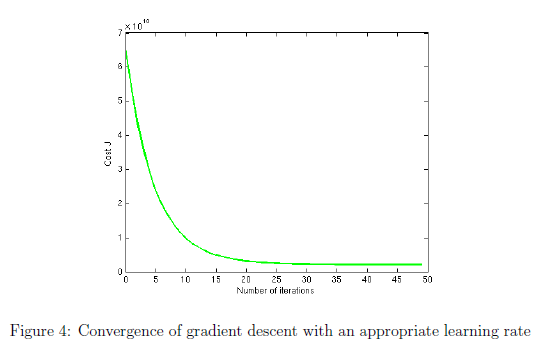

    If your graph looks very different, especially if your value of $J(\theta)$ increases or even blows up, use the control to adjust your learning rate and try again. We recommend trying values of the learning rate on a log-scale, at multiplicative steps of about 3 times the previous value (i.e., 0.3, 0.1, 0.03, 0.01 and so on). You may also want to adjust the number of iterations you are running if that will help you see the overall trend in the curve.

**Implementation Note:** If your learning rate is too large, $J(\theta)$ can diverge and 'blow up', resulting in values which are too large for computer calculations. In these situations, MATLAB will tend to return `NaNs`. `NaN` stands for 'not a number' and is often caused by undefined operations that involve $\pm \;\infty$.

**MATLAB Tip:** To compare how different learning learning rates affect convergence, it's helpful to plot `J` for several learning rates on the same figure. In MATLAB, this can be done by performing gradient descent multiple times with a `hold on` command between plots. Make sure to use the `hold off` command when you are done plotting in that figure. Concretely, if you've tried three different values of `alpha` (you should probably try more values than this) and stored the costs in `J1`, `J2` and `J3`, you can use the following commands to plot them on the same figure:

    The final arguments `'b'`,`'r'`, and `'k``'` specify different colors for the plots. If desired, you can use this technique and adapt the code below to plot multiple convergence histories in the same plot. 

% Run gradient descent:
% Choose some alpha value
alpha = 0.1;
num_iters = 50;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[~, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Plot the convergence graph
plot(1:num_iters, J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');

Notice the changes in the convergence curves as the learning rate changes. With a small learning rate, you should find that gradient descent takes a very long time to converge to the optimal value. Conversely, with a large learning rate, gradient descent might not converge or might even diverge! 

    Using the best learning rate that you found, run the section of code below, which will run gradient descent until convergence to find the final values of $\theta$. Next, use this value of $\theta$ to predict the price of a house with 1650 square feet and 3 bedrooms. You will use value later to check your implementation of the normal equations. Don't forget to normalize your features when you make this prediction!

% Run gradient descent
% Replace the value of alpha below best alpha value you found above
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

delta = 	1.0e+05 *

   -3.4041
   -1.0463
   -0.5412


theta = 	1.0e+04 *

    3.4041
    1.0463
    0.5412


J = 5.3294e+10

delta = 	1.0e+05 *

   -3.0637
   -0.9143
   -0.4309


theta = 	1.0e+04 *

    6.4678
    1.9606
    0.9722


J = 4.3427e+10

delta = 	1.0e+05 *

   -2.7573
   -0.8012
   -0.3386


theta = 	1.0e+04 *

    9.2252
    2.7618
    1.3108


J = 3.5500e+10

delta = 	1.0e+05 *

   -2.4816
   -0.7042
   -0.2616


theta = 	1.0e+05 *

    1.1707
    0.3466
    0.1572


J = 2.9123e+10

delta = 	1.0e+05 *

   -2.2334
   -0.6209
   -0.1974


theta = 	1.0e+05 *

    1.3940
    0.4087
    0.1770


J = 2.3987e+10

delta = 	1.0e+05 *

   -2.0101
   -0.5493
   -0.1440


theta = 	1.0e+05 *

    1.5950
    0.4636
    0.1914


J = 1.9846e+10

delta = 	1.0e+05 *

   -1.8091
   -0.4877
   -0.0998


theta = 	1.0e+05 *

    1.7759
    0.5124
    0.2014


J = 1.6504e+10

delta = 	1.0e+05 *

   -1.6282
   -0.4345
   -0.0633


theta = 	1.0e+05 *

    1.9388
    0.5558
    0.2077


J = 1.3803e+10

delta = 	1.0e+05 *

   -1.4654
   -0.3885
   -0.0333


theta = 	1.0e+05 *

    2.0853
    0.5947
    0.2110


J = 1.1620e+10

delta = 	1.0e+05 *

   -1.3188
   -0.3486
   -0.0088


theta = 	1.0e+05 *

    2.2172
    0.6296
    0.2119


J = 9.8517e+09

delta = 	1.0e+05 *

   -1.1869
   -0.3140
    0.0112


theta = 	1.0e+05 *

    2.3359
    0.6610
    0.2108


J = 8.4192e+09

delta = 	1.0e+05 *

   -1.0683
   -0.2839
    0.0273


theta = 	1.0e+05 *

    2.4427
    0.6893
    0.2081


J = 7.2573e+09

delta = 	1.0e+04 *

   -9.6143
   -2.5762
    0.4019


theta = 	1.0e+05 *

    2.5388
    0.7151
    0.2040


J = 6.3139e+09

delta = 	1.0e+04 *

   -8.6528
   -2.3461
    0.5038


theta = 	1.0e+05 *

    2.6254
    0.7386
    0.1990


J = 5.5472e+09

delta = 	1.0e+04 *

   -7.7875
   -2.1441
    0.5831


theta = 	1.0e+05 *

    2.7032
    0.7600
    0.1932


J = 4.9234e+09

delta = 	1.0e+04 *

   -7.0088
   -1.9662
    0.6435


theta = 	1.0e+05 *

    2.7733
    0.7797
    0.1867


J = 4.4154e+09

delta = 	1.0e+04 *

   -6.3079
   -1.8090
    0.6883


theta = 	1.0e+05 *

    2.8364
    0.7978
    0.1799


J = 4.0011e+09

delta = 	1.0e+04 *

   -5.6771
   -1.6697
    0.7201


theta = 	1.0e+05 *

    2.8932
    0.8145
    0.1727


J = 3.6628e+09

delta = 	1.0e+04 *

   -5.1094
   -1.5458
    0.7411


theta = 	1.0e+05 *

    2.9443
    0.8299
    0.1652


J = 3.3862e+09

delta = 	1.0e+04 *

   -4.5985
   -1.4351
    0.7533


theta = 	1.0e+05 *

    2.9903
    0.8443
    0.1577


J = 3.1597e+09

delta = 	1.0e+04 *

   -4.1386
   -1.3359
    0.7582


theta = 	1.0e+05 *

    3.0317
    0.8576
    0.1501


J = 2.9740e+09

delta = 	1.0e+04 *

   -3.7248
   -1.2467
    0.7572


theta = 	1.0e+05 *

    3.0689
    0.8701
    0.1426


J = 2.8215e+09

delta = 	1.0e+04 *

   -3.3523
   -1.1662
    0.7514


theta = 	1.0e+05 *

    3.1024
    0.8818
    0.1350


J = 2.6959e+09

delta = 	1.0e+04 *

   -3.0171
   -1.0932
    0.7418


theta = 	1.0e+05 *

    3.1326
    0.8927
    0.1276


J = 2.5924e+09

delta = 	1.0e+04 *

   -2.7154
   -1.0269
    0.7291


theta = 	1.0e+05 *

    3.1597
    0.9030
    0.1203


J = 2.5068e+09

delta = 3×1
   -2.4438
   -0.9664
    0.7140


theta = 3×1
    3.1842
    0.9126
    0.1132


J = 2.4360e+09

delta = 3×1
   -2.1994
   -0.9109
    0.6971


theta = 3×1
    3.2062
    0.9217
    0.1062


J = 2.3772e+09

delta = 3×1
   -1.9795
   -0.8600
    0.6788


theta = 3×1
    3.2260
    0.9303
    0.0994


J = 2.3282e+09

delta = 3×1
   -1.7815
   -0.8130
    0.6595


theta = 3×1
    3.2438
    0.9385
    0.0928


J = 2.2874e+09

delta = 3×1
   -1.6034
   -0.7696
    0.6395


theta = 3×1
    3.2598
    0.9462
    0.0864


J = 2.2531e+09

delta = 3×1
   -1.4430
   -0.7293
    0.6191


theta = 3×1
    3.2743
    0.9534
    0.0803


J = 2.2244e+09

delta = 3×1
   -1.2987
   -0.6918
    0.5985


theta = 3×1
    3.2872
    0.9604
    0.0743


J = 2.2002e+09

delta = 3×1
   -1.1689
   -0.6569
    0.5778


theta = 3×1
    3.2989
    0.9669
    0.0685


J = 2.1797e+09

delta = 3×1
   -1.0520
   -0.6243
    0.5573


theta = 3×1
    3.3094
    0.9732
    0.0629


J = 2.1624e+09

delta = 3×1
   -9.4678
   -5.9375
    5.3694


theta = 3×1
    3.3189
    0.9791
    0.0575


J = 2.1476e+09

delta = 3×1
   -8.5211
   -5.6506
    5.1693


theta = 3×1
    3.3274
    0.9848
    0.0524


J = 2.1349e+09

delta = 3×1
   -7.6690
   -5.3809
    4.9731


theta = 3×1
    3.3351
    0.9901
    0.0474


J = 2.1241e+09

delta = 3×1
   -6.9021
   -5.1268
    4.7812


theta = 3×1
    3.3420
    0.9953
    0.0426


J = 2.1148e+09

delta = 3×1
   -6.2119
   -4.8871
    4.5943


theta = 3×1
    3.3482
    1.0002
    0.0380


J = 2.1067e+09

delta = 3×1
   -5.5907
   -4.6605
    4.4124


theta = 3×1
    3.3538
    1.0048
    0.0336


J = 2.0997e+09

delta = 3×1
   -5.0316
   -4.4462
    4.2360


theta = 3×1
    3.3588
    1.0093
    0.0294


J = 2.0936e+09

delta = 3×1
   -4.5284
   -4.2432
    4.0651


theta = 3×1
    3.3634
    1.0135
    0.0253


J = 2.0883e+09

delta = 3×1
   -4.0756
   -4.0507
    3.8998


theta = 3×1
    3.3674
    1.0176
    0.0214


J = 2.0836e+09

delta = 3×1
   -3.6680
   -3.8680
    3.7401


theta = 3×1
    3.3711
    1.0214
    0.0177


J = 2.0795e+09

delta = 3×1
   -3.3012
   -3.6944
    3.5860


theta = 3×1
    3.3744
    1.0251
    0.0141


J = 2.0759e+09

delta = 3×1
   -2.9711
   -3.5294
    3.4375


theta = 3×1
    3.3774
    1.0287
    0.0107


J = 2.0727e+09

delta = 3×1
   -2.6740
   -3.3723
    3.2945


theta = 3×1
    3.3801
    1.0320
    0.0074


J = 2.0698e+09

delta = 3×1
   -2.4066
   -3.2228
    3.1569


theta = 3×1
    3.3825
    1.0353
    0.0042


J = 2.0673e+09

delta = 3×1
   -2.1659
   -3.0804
    3.0246


theta = 3×1
    3.3846
    1.0383
    0.0012


J = 2.0650e+09

delta = 3×1
   -1.9493
   -2.9447
    2.8974


theta = 3×1
    3.3866
    1.0413
   -0.0017


J = 2.0630e+09

delta = 3×1
   -1.7544
   -2.8153
    2.7752


theta = 3×1
    3.3883
    1.0441
   -0.0045


J = 2.0611e+09

delta = 3×1
   -1.5790
   -2.6918
    2.6579


theta = 3×1
    3.3899
    1.0468
   -0.0072


J = 2.0595e+09

delta = 3×1
   -1.4211
   -2.5740
    2.5452


theta = 3×1
    3.3913
    1.0494
   -0.0097


J = 2.0580e+09

delta = 3×1
   -1.2790
   -2.4616
    2.4372


theta = 3×1
    3.3926
    1.0518
   -0.0121


J = 2.0567e+09

delta = 3×1
   -1.1511
   -2.3543
    2.3336


theta = 3×1
    3.3938
    1.0542
   -0.0145


J = 2.0555e+09

delta = 3×1
   -1.0360
   -2.2517
    2.2342


theta = 3×1
    3.3948
    1.0564
   -0.0167


J = 2.0544e+09

delta = 3×1
   -0.9324
   -2.1538
    2.1390


theta = 3×1
    3.3957
    1.0586
   -0.0188


J = 2.0534e+09

delta = 3×1
   -0.8391
   -2.0602
    2.0476


theta = 3×1
    3.3966
    1.0606
   -0.0209


J = 2.0525e+09

delta = 3×1
   -0.7552
   -1.9708
    1.9602


theta = 3×1
    3.3973
    1.0626
   -0.0229


J = 2.0517e+09

delta = 3×1
   -0.6797
   -1.8853
    1.8763


theta = 3×1
    3.3980
    1.0645
   -0.0247


J = 2.0510e+09

delta = 3×1
   -0.6117
   -1.8037
    1.7960


theta = 3×1
    3.3986
    1.0663
   -0.0265


J = 2.0503e+09

delta = 3×1
   -0.5506
   -1.7256
    1.7191


theta = 3×1
    3.3992
    1.0680
   -0.0282


J = 2.0497e+09

delta = 3×1
   -0.4955
   -1.6509
    1.6454


theta = 3×1
    3.3997
    1.0697
   -0.0299


J = 2.0492e+09

delta = 3×1
   -0.4459
   -1.5795
    1.5748


theta = 3×1
    3.4001
    1.0713
   -0.0315


J = 2.0486e+09

delta = 3×1
   -0.4014
   -1.5112
    1.5073


theta = 3×1
    3.4005
    1.0728
   -0.0330


J = 2.0482e+09

delta = 3×1
   -0.3612
   -1.4459
    1.4426


theta = 3×1
    3.4009
    1.0742
   -0.0344


J = 2.0478e+09

delta = 3×1
   -0.3251
   -1.3835
    1.3806


theta = 3×1
    3.4012
    1.0756
   -0.0358


J = 2.0474e+09

delta = 3×1
   -0.2926
   -1.3237
    1.3213


theta = 3×1
    3.4015
    1.0769
   -0.0371


J = 2.0470e+09

delta = 3×1
   -0.2633
   -1.2666
    1.2645


theta = 3×1
    3.4018
    1.0782
   -0.0384


J = 2.0467e+09

delta = 3×1
   -0.2370
   -1.2119
    1.2102


theta = 3×1
    3.4020
    1.0794
   -0.0396


J = 2.0464e+09

delta = 3×1
   -0.2133
   -1.1596
    1.1582


theta = 3×1
    3.4022
    1.0806
   -0.0407


J = 2.0462e+09

delta = 3×1
   -0.1920
   -1.1096
    1.1084


theta = 3×1
    3.4024
    1.0817
   -0.0419


J = 2.0459e+09

delta = 3×1
   -0.1728
   -1.0618
    1.0607


theta = 3×1
    3.4026
    1.0827
   -0.0429


J = 2.0457e+09

delta = 3×1
   -0.1555
   -1.0160
    1.0151


theta = 3×1
    3.4027
    1.0837
   -0.0439


J = 2.0455e+09

delta = 3×1
 -139.9431
 -972.1672
  971.4150


theta = 3×1
    3.4029
    1.0847
   -0.0449


J = 2.0453e+09

delta = 3×1
 -125.9488
 -930.2576
  929.6203


theta = 3×1
    3.4030
    1.0856
   -0.0458


J = 2.0451e+09

delta = 3×1
 -113.3539
 -890.1593
  889.6192


theta = 3×1
    3.4031
    1.0865
   -0.0467


J = 2.0450e+09

delta = 3×1
 -102.0185
 -851.7931
  851.3356


theta = 3×1
    3.4032
    1.0874
   -0.0476


J = 2.0448e+09

delta = 3×1
  -91.8166
 -815.0839
  814.6961


theta = 3×1
    3.4033
    1.0882
   -0.0484


J = 2.0447e+09

delta = 3×1
  -82.6350
 -779.9594
  779.6308


theta = 3×1
    3.4034
    1.0890
   -0.0492


J = 2.0446e+09

delta = 3×1
  -74.3715
 -746.3508
  746.0724


theta = 3×1
    3.4035
    1.0897
   -0.0499


J = 2.0445e+09

delta = 3×1
  -66.9343
 -714.1924
  713.9566


theta = 3×1
    3.4035
    1.0904
   -0.0506


J = 2.0444e+09

delta = 3×1
  -60.2409
 -683.4214
  683.2215


theta = 3×1
    3.4036
    1.0911
   -0.0513


J = 2.0443e+09

delta = 3×1
  -54.2168
 -653.9775
  653.8081


theta = 3×1
    3.4036
    1.0918
   -0.0520


J = 2.0442e+09

delta = 3×1
  -48.7951
 -625.8033
  625.6598


theta = 3×1
    3.4037
    1.0924
   -0.0526


J = 2.0441e+09

delta = 3×1
  -43.9156
 -598.8440
  598.7224


theta = 3×1
    3.4037
    1.0930
   -0.0532


J = 2.0440e+09

delta = 3×1
  -39.5241
 -573.0469
  572.9438


theta = 3×1
    3.4038
    1.0936
   -0.0538


J = 2.0440e+09

delta = 3×1
  -35.5717
 -548.3618
  548.2745


theta = 3×1
    3.4038
    1.0941
   -0.0543


J = 2.0439e+09

delta = 3×1
  -32.0145
 -524.7407
  524.6667


theta = 3×1
    3.4038
    1.0947
   -0.0548


J = 2.0439e+09

delta = 3×1
  -28.8130
 -502.1376
  502.0749


theta = 3×1
    3.4039
    1.0952
   -0.0553


J = 2.0438e+09

delta = 3×1
  -25.9317
 -480.5086
  480.4555


theta = 3×1
    3.4039
    1.0956
   -0.0558


J = 2.0438e+09

delta = 3×1
  -23.3386
 -459.8116
  459.7666


theta = 3×1
    3.4039
    1.0961
   -0.0563


J = 2.0437e+09

delta = 3×1
  -21.0047
 -440.0064
  439.9683


theta = 3×1
    3.4039
    1.0965
   -0.0567


J = 2.0437e+09

delta = 3×1
  -18.9042
 -421.0545
  421.0222


theta = 3×1
    3.4040
    1.0970
   -0.0571


J = 2.0437e+09

delta = 3×1
  -17.0138
 -402.9192
  402.8918


theta = 3×1
    3.4040
    1.0974
   -0.0575


J = 2.0436e+09

delta = 3×1
  -15.3124
 -385.5652
  385.5420


theta = 3×1
    3.4040
    1.0977
   -0.0579


J = 2.0436e+09

delta = 3×1
  -13.7812
 -368.9587
  368.9391


theta = 3×1
    3.4040
    1.0981
   -0.0583


J = 2.0436e+09

delta = 3×1
  -12.4031
 -353.0677
  353.0510


theta = 3×1
    3.4040
    1.0985
   -0.0586


J = 2.0435e+09

delta = 3×1
  -11.1628
 -337.8612
  337.8471


theta = 3×1
    3.4040
    1.0988
   -0.0590


J = 2.0435e+09

delta = 3×1
  -10.0465
 -323.3097
  323.2978


theta = 3×1
    3.4040
    1.0991
   -0.0593


J = 2.0435e+09

delta = 3×1
   -9.0418
 -309.3851
  309.3750


theta = 3×1
    3.4040
    1.0994
   -0.0596


J = 2.0435e+09

delta = 3×1
   -8.1377
 -296.0602
  296.0517


theta = 3×1
    3.4041
    1.0997
   -0.0599


J = 2.0435e+09

delta = 3×1
   -7.3239
 -283.3093
  283.3021


theta = 3×1
    3.4041
    1.1000
   -0.0602


J = 2.0435e+09

delta = 3×1
   -6.5915
 -271.1076
  271.1015


theta = 3×1
    3.4041
    1.1003
   -0.0605


J = 2.0434e+09

delta = 3×1
   -5.9323
 -259.4315
  259.4263


theta = 3×1
    3.4041
    1.1005
   -0.0607


J = 2.0434e+09

delta = 3×1
   -5.3391
 -248.2583
  248.2538


theta = 3×1
    3.4041
    1.1008
   -0.0610


J = 2.0434e+09

delta = 3×1
   -4.8052
 -237.5663
  237.5625


theta = 3×1
    3.4041
    1.1010
   -0.0612


J = 2.0434e+09

delta = 3×1
   -4.3247
 -227.3348
  227.3316


theta = 3×1
    3.4041
    1.1013
   -0.0614


J = 2.0434e+09

delta = 3×1
   -3.8922
 -217.5440
  217.5413


theta = 3×1
    3.4041
    1.1015
   -0.0617


J = 2.0434e+09

delta = 3×1
   -3.5030
 -208.1749
  208.1726


theta = 3×1
    3.4041
    1.1017
   -0.0619


J = 2.0434e+09

delta = 3×1
   -3.1527
 -199.2093
  199.2073


theta = 3×1
    3.4041
    1.1019
   -0.0621


J = 2.0434e+09

delta = 3×1
   -2.8374
 -190.6298
  190.6282


theta = 3×1
    3.4041
    1.1021
   -0.0623


J = 2.0434e+09

delta = 3×1
   -2.5537
 -182.4199
  182.4185


theta = 3×1
    3.4041
    1.1023
   -0.0624


J = 2.0434e+09

delta = 3×1
   -2.2983
 -174.5635
  174.5623


theta = 3×1
    3.4041
    1.1024
   -0.0626


J = 2.0433e+09

delta = 3×1
   -2.0685
 -167.0455
  167.0445


theta = 3×1
    3.4041
    1.1026
   -0.0628


J = 2.0433e+09

delta = 3×1
   -1.8616
 -159.8513
  159.8504


theta = 3×1
    3.4041
    1.1028
   -0.0629


J = 2.0433e+09

delta = 3×1
   -1.6755
 -152.9669
  152.9662


theta = 3×1
    3.4041
    1.1029
   -0.0631


J = 2.0433e+09

delta = 3×1
   -1.5079
 -146.3790
  146.3784


theta = 3×1
    3.4041
    1.1031
   -0.0632


J = 2.0433e+09

delta = 3×1
   -1.3571
 -140.0749
  140.0744


theta = 3×1
    3.4041
    1.1032
   -0.0634


J = 2.0433e+09

delta = 3×1
   -1.2214
 -134.0423
  134.0418


theta = 3×1
    3.4041
    1.1033
   -0.0635


J = 2.0433e+09

delta = 3×1
   -1.0993
 -128.2694
  128.2691


theta = 3×1
    3.4041
    1.1035
   -0.0636


J = 2.0433e+09

delta = 3×1
   -0.9893
 -122.7452
  122.7449


theta = 3×1
    3.4041
    1.1036
   -0.0638


J = 2.0433e+09

delta = 3×1
   -0.8904
 -117.4589
  117.4587


theta = 3×1
    3.4041
    1.1037
   -0.0639


J = 2.0433e+09

delta = 3×1
   -0.8014
 -112.4003
  112.4001


theta = 3×1
    3.4041
    1.1038
   -0.0640


J = 2.0433e+09

delta = 3×1
   -0.7212
 -107.5596
  107.5594


theta = 3×1
    3.4041
    1.1039
   -0.0641


J = 2.0433e+09

delta = 3×1
   -0.6491
 -102.9273
  102.9271


theta = 3×1
    3.4041
    1.1040
   -0.0642


J = 2.0433e+09

delta = 3×1
   -0.5842
  -98.4945
   98.4944


theta = 3×1
    3.4041
    1.1041
   -0.0643


J = 2.0433e+09

delta = 3×1
   -0.5258
  -94.2526
   94.2525


theta = 3×1
    3.4041
    1.1042
   -0.0644


J = 2.0433e+09

delta = 3×1
   -0.4732
  -90.1934
   90.1933


theta = 3×1
    3.4041
    1.1043
   -0.0645


J = 2.0433e+09

delta = 3×1
   -0.4259
  -86.3091
   86.3090


theta = 3×1
    3.4041
    1.1044
   -0.0646


J = 2.0433e+09

delta = 3×1
   -0.3833
  -82.5920
   82.5919


theta = 3×1
    3.4041
    1.1045
   -0.0647


J = 2.0433e+09

delta = 3×1
   -0.3450
  -79.0350
   79.0349


theta = 3×1
    3.4041
    1.1046
   -0.0647


J = 2.0433e+09

delta = 3×1
   -0.3105
  -75.6312
   75.6311


theta = 3×1
    3.4041
    1.1046
   -0.0648


J = 2.0433e+09

delta = 3×1
   -0.2794
  -72.3740
   72.3739


theta = 3×1
    3.4041
    1.1047
   -0.0649


J = 2.0433e+09

delta = 3×1
   -0.2515
  -69.2570
   69.2570


theta = 3×1
    3.4041
    1.1048
   -0.0650


J = 2.0433e+09

delta = 3×1
   -0.2263
  -66.2743
   66.2743


theta = 3×1
    3.4041
    1.1048
   -0.0650


J = 2.0433e+09

delta = 3×1
   -0.2037
  -63.4201
   63.4201


theta = 3×1
    3.4041
    1.1049
   -0.0651


J = 2.0433e+09

delta = 3×1
   -0.1833
  -60.6888
   60.6888


theta = 3×1
    3.4041
    1.1050
   -0.0651


J = 2.0433e+09

delta = 3×1
   -0.1650
  -58.0751
   58.0751


theta = 3×1
    3.4041
    1.1050
   -0.0652


J = 2.0433e+09

delta = 3×1
   -0.1485
  -55.5740
   55.5739


theta = 3×1
    3.4041
    1.1051
   -0.0653


J = 2.0433e+09

delta = 3×1
   -0.1336
  -53.1806
   53.1805


theta = 3×1
    3.4041
    1.1051
   -0.0653


J = 2.0433e+09

delta = 3×1
   -0.1203
  -50.8902
   50.8902


theta = 3×1
    3.4041
    1.1052
   -0.0654


J = 2.0433e+09

delta = 3×1
   -0.1083
  -48.6985
   48.6985


theta = 3×1
    3.4041
    1.1052
   -0.0654


J = 2.0433e+09

delta = 3×1
   -0.0974
  -46.6012
   46.6012


theta = 3×1
    3.4041
    1.1053
   -0.0655


J = 2.0433e+09

delta = 3×1
   -0.0877
  -44.5943
   44.5942


theta = 3×1
    3.4041
    1.1053
   -0.0655


J = 2.0433e+09

delta = 3×1
   -0.0789
  -42.6737
   42.6737


theta = 3×1
    3.4041
    1.1054
   -0.0655


J = 2.0433e+09

delta = 3×1
   -0.0710
  -40.8359
   40.8359


theta = 3×1
    3.4041
    1.1054
   -0.0656


J = 2.0433e+09

delta = 3×1
   -0.0639
  -39.0772
   39.0772


theta = 3×1
    3.4041
    1.1054
   -0.0656


J = 2.0433e+09

delta = 3×1
   -0.0575
  -37.3943
   37.3943


theta = 3×1
    3.4041
    1.1055
   -0.0657


J = 2.0433e+09

delta = 3×1
   -0.0518
  -35.7838
   35.7838


theta = 3×1
    3.4041
    1.1055
   -0.0657


J = 2.0433e+09

delta = 3×1
   -0.0466
  -34.2427
   34.2427


theta = 3×1
    3.4041
    1.1055
   -0.0657


J = 2.0433e+09

delta = 3×1
   -0.0419
  -32.7680
   32.7680


theta = 3×1
    3.4041
    1.1056
   -0.0658


J = 2.0433e+09

delta = 3×1
   -0.0377
  -31.3567
   31.3567


theta = 3×1
    3.4041
    1.1056
   -0.0658


J = 2.0433e+09

delta = 3×1
   -0.0340
  -30.0063
   30.0063


theta = 3×1
    3.4041
    1.1056
   -0.0658


J = 2.0433e+09

delta = 3×1
   -0.0306
  -28.7140
   28.7140


theta = 3×1
    3.4041
    1.1057
   -0.0659


J = 2.0433e+09

delta = 3×1
   -0.0275
  -27.4774
   27.4774


theta = 3×1
    3.4041
    1.1057
   -0.0659


J = 2.0433e+09

delta = 3×1
   -0.0248
  -26.2940
   26.2940


theta = 3×1
    3.4041
    1.1057
   -0.0659


J = 2.0433e+09

delta = 3×1
   -0.0223
  -25.1616
   25.1616


theta = 3×1
    3.4041
    1.1058
   -0.0659


J = 2.0433e+09

delta = 3×1
   -0.0201
  -24.0780
   24.0780


theta = 3×1
    3.4041
    1.1058
   -0.0660


J = 2.0433e+09

delta = 3×1
   -0.0181
  -23.0410
   23.0410


theta = 3×1
    3.4041
    1.1058
   -0.0660


J = 2.0433e+09

delta = 3×1
   -0.0162
  -22.0487
   22.0487


theta = 3×1
    3.4041
    1.1058
   -0.0660


J = 2.0433e+09

delta = 3×1
   -0.0146
  -21.0991
   21.0991


theta = 3×1
    3.4041
    1.1058
   -0.0660


J = 2.0433e+09

delta = 3×1
   -0.0132
  -20.1905
   20.1905


theta = 3×1
    3.4041
    1.1059
   -0.0660


J = 2.0433e+09

delta = 3×1
   -0.0118
  -19.3209
   19.3209


theta = 3×1
    3.4041
    1.1059
   -0.0661


J = 2.0433e+09

delta = 3×1
   -0.0107
  -18.4888
   18.4888


theta = 3×1
    3.4041
    1.1059
   -0.0661


J = 2.0433e+09

delta = 3×1
   -0.0096
  -17.6926
   17.6926


theta = 3×1
    3.4041
    1.1059
   -0.0661


J = 2.0433e+09

delta = 3×1
   -0.0086
  -16.9306
   16.9306


theta = 3×1
    3.4041
    1.1059
   -0.0661


J = 2.0433e+09

delta = 3×1
   -0.0078
  -16.2014
   16.2014


theta = 3×1
    3.4041
    1.1060
   -0.0661


J = 2.0433e+09

delta = 3×1
   -0.0070
  -15.5037
   15.5037


theta = 3×1
    3.4041
    1.1060
   -0.0662


J = 2.0433e+09

delta = 3×1
   -0.0063
  -14.8360
   14.8360


theta = 3×1
    3.4041
    1.1060
   -0.0662


J = 2.0433e+09

delta = 3×1
   -0.0057
  -14.1971
   14.1971


theta = 3×1
    3.4041
    1.1060
   -0.0662


J = 2.0433e+09

delta = 3×1
   -0.0051
  -13.5856
   13.5856


theta = 3×1
    3.4041
    1.1060
   -0.0662


J = 2.0433e+09

delta = 3×1
   -0.0046
  -13.0005
   13.0005


theta = 3×1
    3.4041
    1.1060
   -0.0662


J = 2.0433e+09

delta = 3×1
   -0.0041
  -12.4406
   12.4406


theta = 3×1
    3.4041
    1.1060
   -0.0662


J = 2.0433e+09

delta = 3×1
   -0.0037
  -11.9049
   11.9049


theta = 3×1
    3.4041
    1.1060
   -0.0662


J = 2.0433e+09

delta = 3×1
   -0.0033
  -11.3922
   11.3922


theta = 3×1
    3.4041
    1.1061
   -0.0662


J = 2.0433e+09

delta = 3×1
   -0.0030
  -10.9015
   10.9015


theta = 3×1
    3.4041
    1.1061
   -0.0663


J = 2.0433e+09

delta = 3×1
   -0.0027
  -10.4320
   10.4320


theta = 3×1
    3.4041
    1.1061
   -0.0663


J = 2.0433e+09

delta = 3×1
   -0.0024
   -9.9828
    9.9828


theta = 3×1
    3.4041
    1.1061
   -0.0663


J = 2.0433e+09

delta = 3×1
   -0.0022
   -9.5528
    9.5528


theta = 3×1
    3.4041
    1.1061
   -0.0663


J = 2.0433e+09

delta = 3×1
   -0.0020
   -9.1414
    9.1414


theta = 3×1
    3.4041
    1.1061
   -0.0663


J = 2.0433e+09

delta = 3×1
   -0.0018
   -8.7477
    8.7477


theta = 3×1
    3.4041
    1.1061
   -0.0663


J = 2.0433e+09

delta = 3×1
   -0.0016
   -8.3710
    8.3710


theta = 3×1
    3.4041
    1.1061
   -0.0663


J = 2.0433e+09

delta = 3×1
   -0.0014
   -8.0105
    8.0105


theta = 3×1
    3.4041
    1.1061
   -0.0663


J = 2.0433e+09

delta = 3×1
   -0.0013
   -7.6655
    7.6655


theta = 3×1
    3.4041
    1.1061
   -0.0663


J = 2.0433e+09

delta = 3×1
   -0.0012
   -7.3354
    7.3354


theta = 3×1
    3.4041
    1.1061
   -0.0663


J = 2.0433e+09

delta = 3×1
   -0.0010
   -7.0194
    7.0194


theta = 3×1
    3.4041
    1.1062
   -0.0663


J = 2.0433e+09

delta = 3×1
   -0.0009
   -6.7171
    6.7171


theta = 3×1
    3.4041
    1.1062
   -0.0663


J = 2.0433e+09

delta = 3×1
   -0.0009
   -6.4278
    6.4278


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0008
   -6.1510
    6.1510


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0007
   -5.8861
    5.8861


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0006
   -5.6326
    5.6326


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0006
   -5.3900
    5.3900


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0005
   -5.1579
    5.1579


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0005
   -4.9358
    4.9358


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0004
   -4.7232
    4.7232


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0004
   -4.5198
    4.5198


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0003
   -4.3251
    4.3251


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0003
   -4.1389
    4.1389


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0003
   -3.9606
    3.9606


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0002
   -3.7900
    3.7900


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0002
   -3.6268
    3.6268


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0002
   -3.4706
    3.4706


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0002
   -3.3211
    3.3211


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0002
   -3.1781
    3.1781


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0001
   -3.0412
    3.0412


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0001
   -2.9103
    2.9103


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0001
   -2.7849
    2.7849


theta = 3×1
    3.4041
    1.1062
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0001
   -2.6650
    2.6650


theta = 3×1
    3.4041
    1.1063
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0001
   -2.5502
    2.5502


theta = 3×1
    3.4041
    1.1063
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0001
   -2.4404
    2.4404


theta = 3×1
    3.4041
    1.1063
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0001
   -2.3353
    2.3353


theta = 3×1
    3.4041
    1.1063
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0001
   -2.2347
    2.2347


theta = 3×1
    3.4041
    1.1063
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0001
   -2.1385
    2.1385


theta = 3×1
    3.4041
    1.1063
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0001
   -2.0464
    2.0464


theta = 3×1
    3.4041
    1.1063
   -0.0664


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.9582
    1.9582


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.8739
    1.8739


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.7932
    1.7932


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.7160
    1.7160


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.6421
    1.6421


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.5714
    1.5714


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.5037
    1.5037


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.4389
    1.4389


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.3770
    1.3770


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.3176
    1.3176


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.2609
    1.2609


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.2066
    1.2066


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.1546
    1.1546


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.1049
    1.1049


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.0573
    1.0573


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -1.0118
    1.0118


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.9682
    0.9682


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.9265
    0.9265


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.8866
    0.8866


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.8484
    0.8484


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.8119
    0.8119


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.7769
    0.7769


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.7435
    0.7435


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.7114
    0.7114


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.6808
    0.6808


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.6515
    0.6515


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.6234
    0.6234


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.5966
    0.5966


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.5709
    0.5709


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.5463
    0.5463


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.5228
    0.5228


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.5003
    0.5003


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.4787
    0.4787


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.4581
    0.4581


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.4384
    0.4384


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.4195
    0.4195


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.4014
    0.4014


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.3841
    0.3841


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.3676
    0.3676


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.3518
    0.3518


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.3366
    0.3366


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.3221
    0.3221


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.3082
    0.3082


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.2950
    0.2950


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.2823
    0.2823


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.2701
    0.2701


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.2585
    0.2585


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.2473
    0.2473


theta = 3×1
    3.4041
    1.1063
   -0.0665


J = 2.0433e+09

delta = 3×1
   -0.0000
   -0.2367
    0.2367


theta = 3×1
    3.4041
    1.1063
   -0.0665



% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

% Estimate the price of a 1650 sq-ft, 3 br house. You can use the same
% code you entered ealier to predict the price
% ====================== YOUR CODE HERE ======================
x = [1650 3]
x = (x-mu)./sigma
x = [1 x]
price = x*theta; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

### 3.3 Normal Equations

In the lecture videos, you learned that the closed-form solution to linear regression is


$$\theta = \left(X^T X\right)^{-1} X^T \vec{y} $$


    Using this formula does not require any feature scaling, and you will get an exact solution in one calculation: there is no "loop until convergence" like in gradient descent.

    Complete the code in `normalEqn.m` to use the formula above to calculate $\theta$, then run the code in this section. Remember that while you don't need to scale your features, we still need to add a column of 1's to the `X` matrix to have an intercept term ($\theta_0$) . Note that the code below will add the column of 1's to `X` for you.

% Solve with normal equations:
% Load Data
data = csvread('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Add intercept term to X
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
theta = normalEqn(X, y);

% Display normal equation's result
fprintf('Theta computed from the normal equations:\n%f\n%f\n%f', theta(1),theta(2),theta(3));

**Optional (ungraded) exercise: **Now, once you have found $\theta$ using this method, use it to make a price prediction for a 1650-square-foot house with 3 bedrooms. You should find that gives the same predicted price as the value you obtained using the model fit with gradient descent (in Section 3.2.1).

% Estimate the price of a 1650 sq-ft, 3 br house. 
% ====================== YOUR CODE HERE ======================

price = [1 1650 3]*theta; % Enter your price forumla here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using normal equations):\n $%f', price);     

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

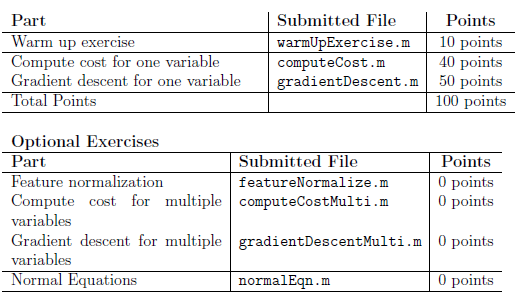

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.